### SA算法收敛性分析

本段测试不同迭代次数（也即仿真采样的次数）下选择到最优值的概率，每个迭代次数下进行50次仿真并取平均值。

SA_result = zeros(40,4);
iValues = 1:5:200;

parfor idx = 1:numel(iValues)
	k = iValues(idx);
    temporary_result = zeros(50,3);
    for seed = 1:50
        [I,i,t]  = SA(seed*k,k*1000);
        temporary_result(seed,:) = [I,i,t];
    end
    temporary_result(:,[1,2]) = (temporary_result(:,[1,2]) == 10);
    SA_result(idx,:) = [k,mean(temporary_result,1)];
end

右图横轴为迭代次数（也即仿真采样的次数），单位为千次。纵轴为选到最优值的概率。

可以发现，随着迭代次数的提升，算法的准确率逐渐提升，在10万后趋于稳定，可以收敛到1.

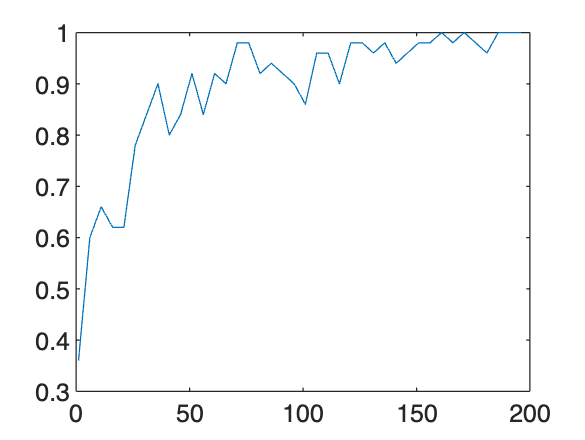

load("SA_result.mat")
plot(SA_result(:,1),SA_result(:,2))

### 比较SA与KN

我们比较SA与KN在仿真采样次数、计算时间、准确率上的区别。其中SA的仿真采样数量确定为10万。

result = zeros(1000,6);
parfor seed = 1:1000
    [I,i,t]  = SA(seed,100000);
    [I_KN,r_KN,t_KN] = KN(seed);
    result(seed,:) = [I,i,t,I_KN,r_KN,t_KN];
end

- 在SA算法可选的两种最优值选定原则中，依照最佳仿真值选择最优解的方法，要优于按照访问次数选择最优解的方法。

- KN算法平均的仿真采样是1万次左右，并且准确率更高，时间更短。

- 为了充分利用SA作为一种启发式算法的特点，不应期待其寻找最优解的准确率，而应当将其作为初期启动算法，快速筛选出有希望的候选参数，缩小可行域范围。

load("VS_result.mat")
result = VS_result;
result(:,[1,2,4]) = (result(:,[1,2,4]) == 10);

依次为：SA最优采样准则下的正确率，SA最多访问准则下的正确率，SA平均时间（秒），KN正确率，KN平均时间（秒）

mean_result = mean(result(:,[1,2,3,4,6]),1)

KN算法的评价仿真采样次数约为1万次

mean(result(:,5))

mean_result =     0.9360    0.8770    2.2243    1.0000    0.5062


ans = 9.8936e+03